clf reset
clc
lab_data_5v = readtable("comb_part1.csv");
simu_v5k100 = readtable("100k5v_simu.csv");
simu_v5k20 = readtable("20k5v_simu.csv");

real_t_1 = table2array(lab_data_5v(:,"t_1"));
real_t_2 = table2array(lab_data_5v(:,"t_2"));
real_v_in_100k_5v = table2array(lab_data_5v(:,"v_1"));
real_v_out_100k_5v = table2array(lab_data_5v(:,"v_2"));
real_v_in_20k_5v = table2array(lab_data_5v(:,"v_1_20"));
real_v_out_20k_5v = table2array(lab_data_5v(:,"v_2_20"));

simu_v_in_100k_5v = table2array(simu_v5k100(:,"vin"));
simu_v_out_100k_5v = table2array(simu_v5k100(:,"vout"));
simu_v_in_20k_5v = table2array(simu_v5k20(:,"vin_20k"));
simu_v_out_20k_5v = table2array(simu_v5k20(:,"vout_20k"));

100k real vs simu

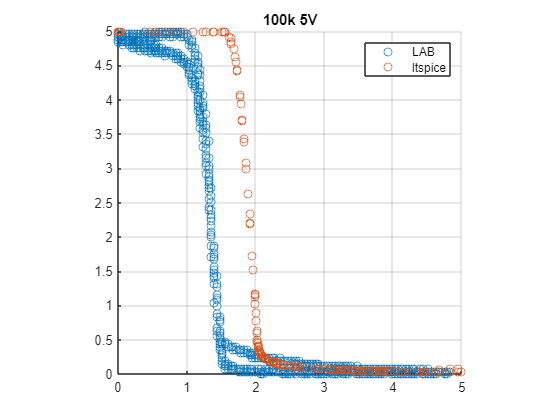

hold on
scatter(real_v_in_100k_5v, real_v_out_100k_5v)
scatter(simu_v_in_100k_5v, simu_v_out_100k_5v)
title("100k 5V")
grid on
axis square
xlim([0 5])
ylim([0 5])
legend("LAB", "ltspice")
hold off

20K real vs simu

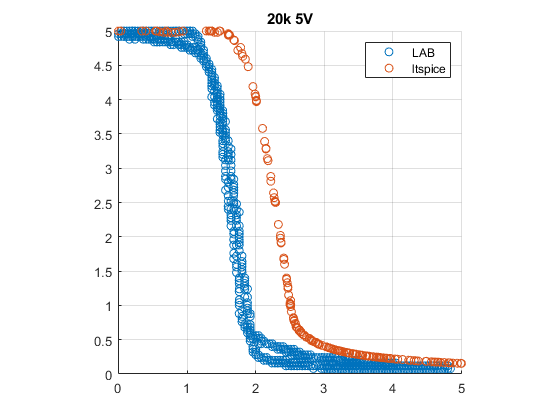

figure
hold on
scatter(real_v_in_20k_5v, real_v_out_20k_5v)
scatter(simu_v_in_20k_5v, simu_v_out_20k_5v)
title("20k 5V")
grid on
axis square
xlim([0 5])
ylim([0 5])
legend("LAB", "ltspice")
hold off

100k real vs real

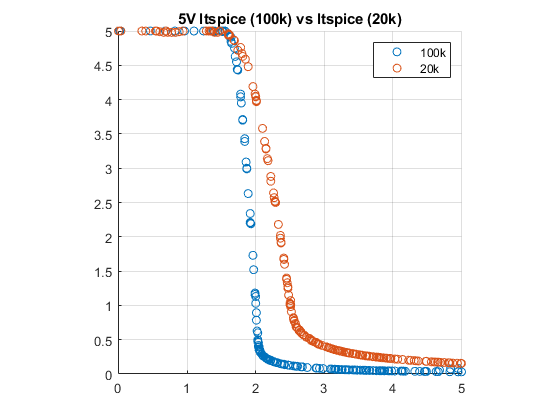

figure
hold on
scatter(simu_v_in_100k_5v, simu_v_out_100k_5v)
scatter(simu_v_in_20k_5v, simu_v_out_20k_5v)
title("5V ltspice (100k) vs ltspice (20k)")
grid on
axis square
xlim([0 5])
ylim([0 5])
legend("100k", "20k")
hold off

100k simu vs simu

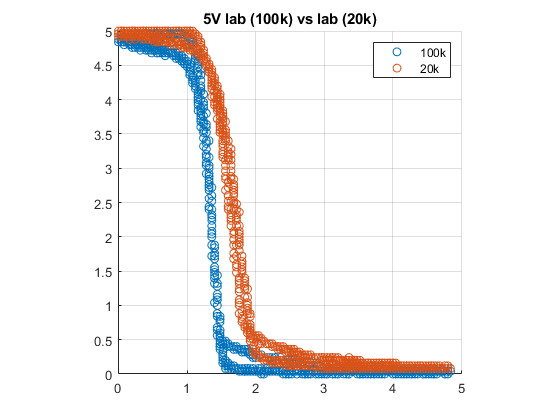

figure
hold on
scatter(real_v_in_100k_5v, real_v_out_100k_5v)
scatter(real_v_in_20k_5v, real_v_out_20k_5v)
title("5V lab (100k) vs lab (20k)")
grid on
axis square
xlim([0 5])
ylim([0 5])
legend("100k", "20k")
hold off

YT plots

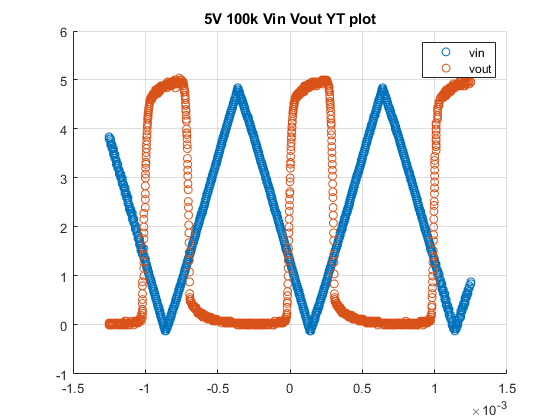

figure
hold on
scatter(real_t_1, real_v_in_100k_5v)
scatter(real_t_2, real_v_out_100k_5v)
title("5V 100k Vin Vout YT plot")
grid on
legend("vin", "vout")
hold off

Find critical points

function [v_oh, v_ol, v_ih, v_il v_th] = find_crit_points(input_voltage, output_voltage)
    vtc = output_voltage / input_voltage;
end